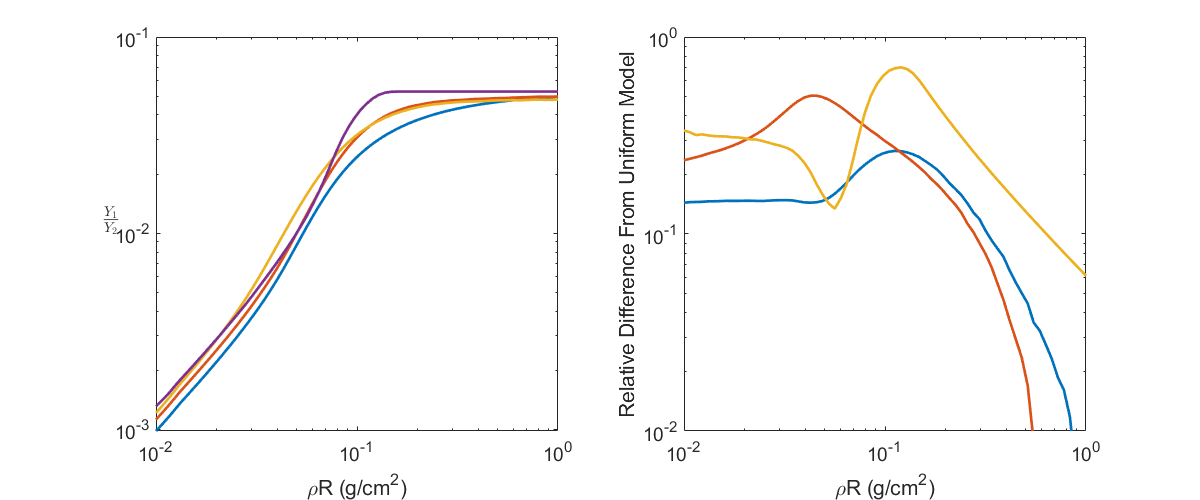

data = xlsread("yieldRatioProfiles.xlsx", '1e6');


figure('Position', [100 100, 1200, 500])
subplot(1,2,1); hold on; box on;
set(gca, 'XScale', 'log', 'YScale', 'log')
set(gca, 'FontSize', 14)
xlim([1e-2, 1])
xlabel('\rhoR (g/cm^2)')
ylabel('$\frac{Y_1}{Y_2}$', 'Interpreter',"latex", 'Rotation', 0)

for i = 2*[1 3 5 7]
    plot(data(:,i-1), smooth(data(:,i),10), 'LineWidth', 2)
end


subplot(1,2,2); hold on; box on;
set(gca, 'XScale', 'log', 'YScale', 'log')
xlim([1e-2, 1])
ylim([1e-2, 1])
set(gca, 'FontSize', 14)
xlabel('\rhoR (g/cm^2)')
ylabel('Relative Difference From Uniform Model')

for i = 2*[3 5 7]
    plot(data(:,i-1), (smooth(data(:,i),10) - smooth(data(:,2),10))./smooth(data(:,2),10), 'LineWidth', 2)    
end

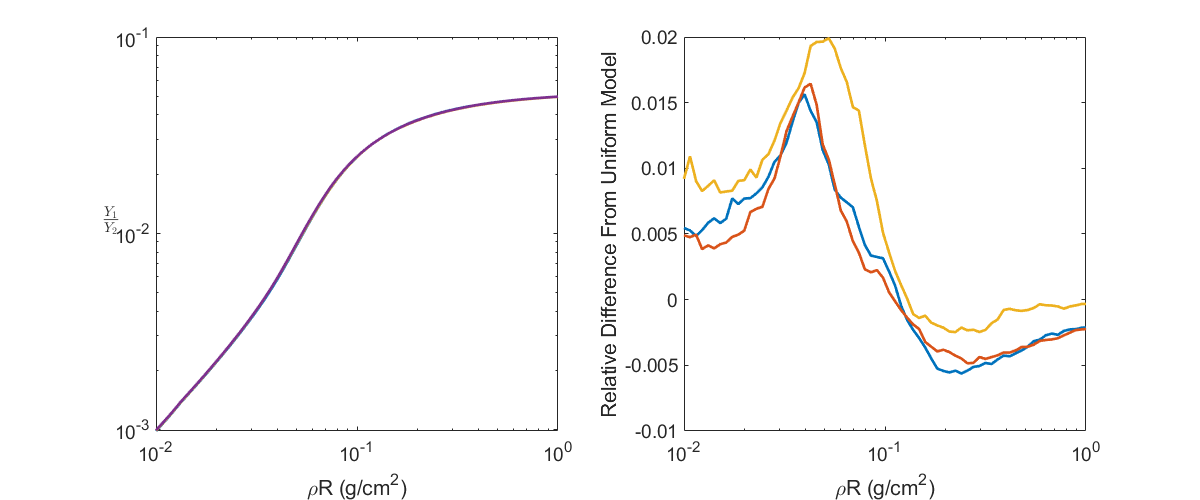








data = xlsread("yieldRatioProfiles.xlsx", 'P2s');


figure('Position', [100 100, 1200, 500])
subplot(1,2,1); hold on; box on;
set(gca, 'XScale', 'log', 'YScale', 'log')
set(gca, 'FontSize', 14)
xlim([1e-2, 1])
xlabel('\rhoR (g/cm^2)')
ylabel('$\frac{Y_1}{Y_2}$', 'Interpreter',"latex", 'Rotation', 0)

for i = 2*[1 2 3 4]
    plot(data(:,i-1), smooth(data(:,i),10), 'LineWidth', 2)
end


subplot(1,2,2); hold on; box on;
set(gca, 'XScale', 'log')
xlim([1e-2, 1])
set(gca, 'FontSize', 14)
xlabel('\rhoR (g/cm^2)')
ylabel('Relative Difference From Uniform Model')

for i = 2*[2 3 4]
    plot(data(:,i-1), (smooth(data(:,i),10) - smooth(data(:,2),10))./smooth(data(:,2),10), 'LineWidth', 2)    
end